clear;clc;close all;
set(0,'defaultlinelinewidth',3)
set(0,'defaultaxeslinewidth',2);
set(0,'defaultaxesfontsize',28);
set(0,'defaulttextfontsize',28);
set(0,'DefaultLineMarkerSize',28);
set(0,'Defaultaxesfontname','Times New Roman');
% addpath('./circleData');

% figure(); box on;
% plot(x/D,U0_axi,'-');
% xlabel('$x/D$','interpreter','latex');
% ylabel('$U_0$','interpreter','latex');
% set(gcf,'unit','centimeters','position',[20 20 20 20])

% saveas(gcf,'Re_80_U0_axi','epsc')

## **18.3.4（2）**

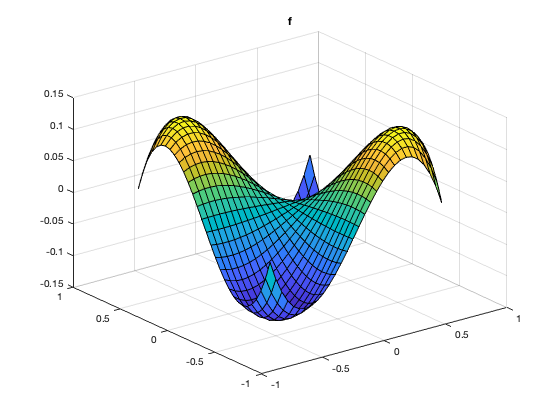

max = 0.7;
t = linspace(-max,max,30);
[x,y] = meshgrid(t);
f = x.*y.*(x.^2+y.^2-1);

surf(x,y,f)
title('f')

## **18.3.4（5）**

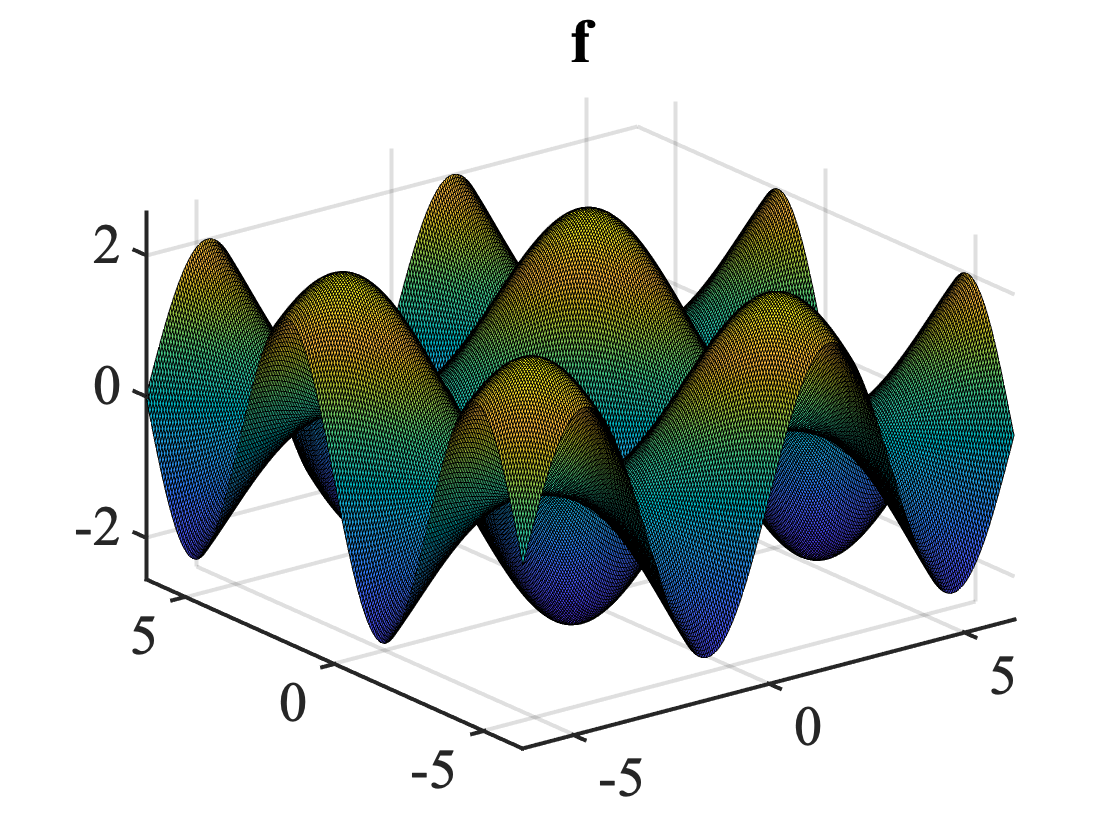

max = 2*pi;
t = linspace(-max,max,300);
[x,y] = meshgrid(t);
f = sin(x)+sin(y)+sin(x+y);

surf(x,y,f)
title('f')

## 18.3.5

syms x y z H(x,y,z)
f=(x+y+z)*exp(-x^2-y^2-z^2)

$$f = {\mathrm{e}}^{-x^{2}-y^{2}-z^{2}}\,\left(x+y+z\right)$$

J=jacobian(f,[x;y;z]);
H(x,y,z)=jacobian(J,[x;y;z])

$$H(x, y, z) = \begin{array}{l} \left(\begin{array}{ccc} 4\,x^{2}\,\sigma_{4}\,\left(x+y+z\right)-2\,\sigma_{4}\,\left(x+y+z\right)-4\,x\,\sigma_{4} & \sigma_{3} & \sigma_{2}\\ \sigma_{3} & 4\,y^{2}\,\sigma_{4}\,\left(x+y+z\right)-2\,\sigma_{4}\,\left(x+y+z\right)-4\,y\,\sigma_{4} & \sigma_{1}\\ \sigma_{2} & \sigma_{1} & 4\,z^{2}\,\sigma_{4}\,\left(x+y+z\right)-2\,\sigma_{4}\,\left(x+y+z\right)-4\,z\,\sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=4\,y\,z\,\sigma_{4}\,\left(x+y+z\right)-2\,z\,\sigma_{4}-2\,y\,\sigma_{4}\\ \sigma_{2}=4\,x\,z\,\sigma_{4}\,\left(x+y+z\right)-2\,z\,\sigma_{4}-2\,x\,\sigma_{4}\\ \sigma_{3}=4\,x\,y\,\sigma_{4}\,\left(x+y+z\right)-2\,y\,\sigma_{4}-2\,x\,\sigma_{4}\\ \sigma_{4}={\mathrm{e}}^{-x^{2}-y^{2}-z^{2}} \end{array}$$

a = -sqrt(6)/6;
H(a,a,a)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \frac{4\,\sqrt{6}\,{\mathrm{e}}^{-\frac{1}{2}}}{3} & \sigma_{1} & \sigma_{1}\\ \sigma_{1} & \frac{4\,\sqrt{6}\,{\mathrm{e}}^{-\frac{1}{2}}}{3} & \sigma_{1}\\ \sigma_{1} & \sigma_{1} & \frac{4\,\sqrt{6}\,{\mathrm{e}}^{-\frac{1}{2}}}{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{6}\,{\mathrm{e}}^{-\frac{1}{2}}}{3} \end{array}$$

## 16.3.6(3)

syms z
x = -3-sqrt(sym(6))

$$x = -\sqrt{6}-3$$


simplify(2*x^2+z^2-2*x*z+4*x+2*z-2)

$$ans = \left(z+4\right)\,\left(z+2\,\sqrt{6}+4\right)$$

## `18.4.5(3)`

syms l m n a b c x
f=l^2/(x-a^2)+m^2/(x-b^2)+n^2/(x-c^2)

$$f = \frac{l^{2}}{x-a^{2}}+\frac{m^{2}}{x-b^{2}}+\frac{n^{2}}{x-c^{2}}$$

x=simplify(solve(f==0,x))

$$x = \begin{array}{l} \left(\begin{array}{c} \frac{\sigma_{1}+\sigma_{8}+\sigma_{7}+\sigma_{6}+\sigma_{5}+\sigma_{4}+\sigma_{3}}{\sigma_{2}}\\ \frac{\sigma_{8}-\sigma_{1}+\sigma_{7}+\sigma_{6}+\sigma_{5}+\sigma_{4}+\sigma_{3}}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{a^{4}\,m^{4}+2\,a^{4}\,m^{2}\,n^{2}+a^{4}\,n^{4}+2\,a^{2}\,b^{2}\,l^{2}\,m^{2}-2\,a^{2}\,b^{2}\,l^{2}\,n^{2}-2\,a^{2}\,b^{2}\,m^{2}\,n^{2}-2\,a^{2}\,b^{2}\,n^{4}-2\,a^{2}\,c^{2}\,l^{2}\,m^{2}+2\,a^{2}\,c^{2}\,l^{2}\,n^{2}-2\,a^{2}\,c^{2}\,m^{4}-2\,a^{2}\,c^{2}\,m^{2}\,n^{2}+b^{4}\,l^{4}+2\,b^{4}\,l^{2}\,n^{2}+b^{4}\,n^{4}-2\,b^{2}\,c^{2}\,l^{4}-2\,b^{2}\,c^{2}\,l^{2}\,m^{2}-2\,b^{2}\,c^{2}\,l^{2}\,n^{2}+2\,b^{2}\,c^{2}\,m^{2}\,n^{2}+c^{4}\,l^{4}+2\,c^{4}\,l^{2}\,m^{2}+c^{4}\,m^{4}}\\ \sigma_{2}=2\,\left(l^{2}+m^{2}+n^{2}\right)\\ \sigma_{3}=c^{2}\,m^{2}\\ \sigma_{4}=b^{2}\,n^{2}\\ \sigma_{5}=c^{2}\,l^{2}\\ \sigma_{6}=a^{2}\,n^{2}\\ \sigma_{7}=b^{2}\,l^{2}\\ \sigma_{8}=a^{2}\,m^{2} \end{array}$$

syms l m n a b c x y
f = (x^2+y^2)^2-x^2-y^2

$$f = {\left(x^{2}+y^{2}\right)}^{2}-x^{2}-y^{2}$$

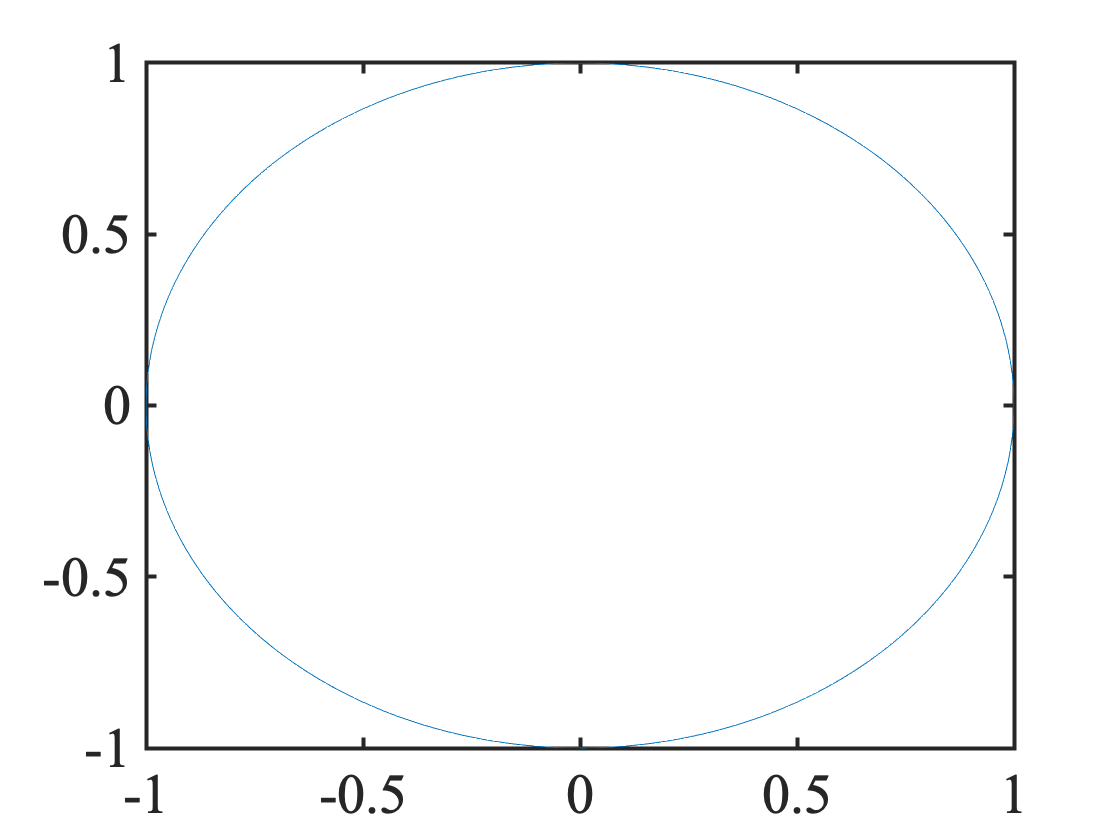

fimplicit(@(x,y) (x^2+y^2)^2-x^2-y^2)

## `18.4.5(4)`

syms l m n a b c x
f=l^2*a^4/(1-a^2*x)+m^2*b^4/(1-b^2*x)+n^2*c^4/(1-c^2*x)

$$f = -\frac{a^{4}\,l^{2}}{a^{2}\,x-1}-\frac{b^{4}\,m^{2}}{b^{2}\,x-1}-\frac{c^{4}\,n^{2}}{c^{2}\,x-1}$$

x=simplify(solve(f==0,x))

$$x = \begin{array}{l} \left(\begin{array}{c} \frac{\sigma_{8}-\sigma_{1}+\sigma_{7}+\sigma_{6}+\sigma_{5}+\sigma_{4}+\sigma_{3}}{\sigma_{2}}\\ \frac{\sigma_{1}+\sigma_{8}+\sigma_{7}+\sigma_{6}+\sigma_{5}+\sigma_{4}+\sigma_{3}}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{a^{8}\,b^{4}\,l^{4}-2\,a^{8}\,b^{2}\,c^{2}\,l^{4}+a^{8}\,c^{4}\,l^{4}+2\,a^{6}\,b^{6}\,l^{2}\,m^{2}-2\,a^{6}\,b^{4}\,c^{2}\,l^{2}\,m^{2}-2\,a^{6}\,b^{2}\,c^{4}\,l^{2}\,n^{2}+2\,a^{6}\,c^{6}\,l^{2}\,n^{2}+a^{4}\,b^{8}\,m^{4}-2\,a^{4}\,b^{6}\,c^{2}\,l^{2}\,m^{2}+2\,a^{4}\,b^{4}\,c^{4}\,l^{2}\,m^{2}+2\,a^{4}\,b^{4}\,c^{4}\,l^{2}\,n^{2}+2\,a^{4}\,b^{4}\,c^{4}\,m^{2}\,n^{2}-2\,a^{4}\,b^{2}\,c^{6}\,l^{2}\,n^{2}+a^{4}\,c^{8}\,n^{4}-2\,a^{2}\,b^{8}\,c^{2}\,m^{4}-2\,a^{2}\,b^{6}\,c^{4}\,m^{2}\,n^{2}-2\,a^{2}\,b^{4}\,c^{6}\,m^{2}\,n^{2}-2\,a^{2}\,b^{2}\,c^{8}\,n^{4}+b^{8}\,c^{4}\,m^{4}+2\,b^{6}\,c^{6}\,m^{2}\,n^{2}+b^{4}\,c^{8}\,n^{4}}\\ \sigma_{2}=2\,a^{2}\,b^{2}\,c^{2}\,\left(a^{2}\,l^{2}+b^{2}\,m^{2}+c^{2}\,n^{2}\right)\\ \sigma_{3}=b^{2}\,c^{4}\,n^{2}\\ \sigma_{4}=b^{4}\,c^{2}\,m^{2}\\ \sigma_{5}=a^{2}\,c^{4}\,n^{2}\\ \sigma_{6}=a^{4}\,c^{2}\,l^{2}\\ \sigma_{7}=a^{2}\,b^{4}\,m^{2}\\ \sigma_{8}=a^{4}\,b^{2}\,l^{2} \end{array}$$

## 18.4.6

syms x y z l
a = 3*x^2-2*y*z+2*l*x

$$a = 3\,x^{2}+2\,l\,x-2\,y\,z$$

b = 3*y^2-2*x*z+2*l*y

$$b = 3\,y^{2}+2\,l\,y-2\,x\,z$$

c = 3*z^2-2*x*y+2*l*z

$$c = 3\,z^{2}+2\,l\,z-2\,x\,y$$

d = x^2+y^2+z^2-1

$$d = x^{2}+y^{2}+z^{2}-1$$

eqns=[a==0,b==0,c==0,d==0]; % 定义方程组
vars=[x,y,z,l]; % 定义求解的未知量
[x,y,z,l]=solve(eqns,vars)

$$x = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}+\frac{\sqrt{6}}{12}\\ \frac{\sqrt{6}}{12}-\sigma_{1}\\ \sigma_{1}-\frac{\sqrt{6}}{12}\\ -\sigma_{1}-\frac{\sqrt{6}}{12}\\ \frac{\sqrt{3}}{3}\\ -\frac{\sqrt{3}}{3}\\ \frac{5\,\sqrt{6}}{18}\\ -\frac{5\,\sqrt{6}}{18}\\ 1\\ -1\\ 0\\ 0\\ 0\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{7\,\sqrt{3}\,\sqrt{8}}{72} \end{array}$$

$$y = \begin{array}{l} \left(\begin{array}{c} \frac{\sqrt{6}}{12}-\sigma_{1}\\ \sigma_{1}+\frac{\sqrt{6}}{12}\\ -\sigma_{1}-\frac{\sqrt{6}}{12}\\ \sigma_{1}-\frac{\sqrt{6}}{12}\\ \frac{\sqrt{3}}{3}\\ -\frac{\sqrt{3}}{3}\\ \frac{5\,\sqrt{6}}{18}\\ -\frac{5\,\sqrt{6}}{18}\\ 0\\ 0\\ 1\\ -1\\ 0\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{7\,\sqrt{3}\,\sqrt{8}}{72} \end{array}$$

$$z = \left(\begin{array}{c} \frac{5\,\sqrt{6}}{18}\\ \frac{5\,\sqrt{6}}{18}\\ -\frac{5\,\sqrt{6}}{18}\\ -\frac{5\,\sqrt{6}}{18}\\ \frac{\sqrt{3}}{3}\\ -\frac{\sqrt{3}}{3}\\ -\frac{\sqrt{6}}{9}\\ \frac{\sqrt{6}}{9}\\ 0\\ 0\\ 0\\ 0\\ 1\\ -1 \end{array}\right)$$

$$l = \left(\begin{array}{c} -\frac{19\,\sqrt{6}}{36}\\ -\frac{19\,\sqrt{6}}{36}\\ \frac{19\,\sqrt{6}}{36}\\ \frac{19\,\sqrt{6}}{36}\\ -\frac{\sqrt{3}}{6}\\ \frac{\sqrt{3}}{6}\\ -\frac{19\,\sqrt{6}}{36}\\ \frac{19\,\sqrt{6}}{36}\\ -\frac{3}{2}\\ \frac{3}{2}\\ -\frac{3}{2}\\ \frac{3}{2}\\ -\frac{3}{2}\\ \frac{3}{2} \end{array}\right)$$

simplify(x.^3+y.^3+z.^3-2*x.*y.*z)

$$ans = \left(\begin{array}{c} \frac{19\,\sqrt{6}}{54}\\ \frac{19\,\sqrt{6}}{54}\\ -\frac{19\,\sqrt{6}}{54}\\ -\frac{19\,\sqrt{6}}{54}\\ \frac{\sqrt{3}}{9}\\ -\frac{\sqrt{3}}{9}\\ \frac{19\,\sqrt{6}}{54}\\ -\frac{19\,\sqrt{6}}{54}\\ 1\\ -1\\ 1\\ -1\\ 1\\ -1 \end{array}\right)$$